syms q1 q2 q3 q4 q5 q6 real
L1 = 1;
L2 = 2;
L3 = 1;
L = [L1, L2 L3];
q_test = [0 0 0 0 0 0];

# **NUMERICAL DERIVATIVES**

H = simplify(Rz(q1) * Tz(L1) * Rx(q2) * Ty(L2) * Rx(q3) * Ty(L3) * Ry(q4) * Rx(q5) * Ry(q6))

R = simplify(H(1:3,1:3))

J1p = Rzd(q1) * Tz(L1) * Rx(q2) * Ty(L2) * Rx(q3) * Ty(L3) * Ry(q4) * Rx(q5) * Ry(q6);
J1p = simplify(J1p);

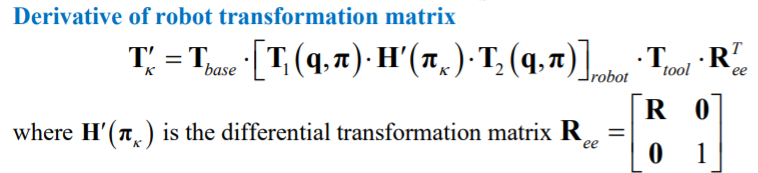

J1r = Rzd(q1) * Tz(L1) * Rx(q2) * Ty(L2) * Rx(q3) * Ty(L3) * Ry(q4) * Rx(q5) * Ry(q6)*...
    [R^-1 zeros(3,1);0 0 0 1];
J1r = simplify(J1r);

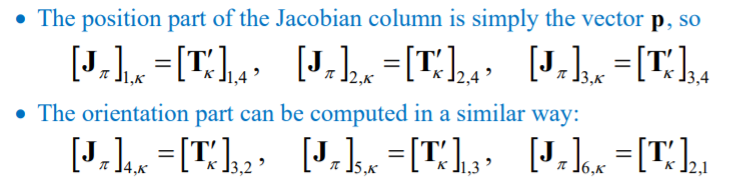

J1e = [J1r(1,4); J1r(2,4); J1r(3,4); J1r(3,2); J1r(1,3); J1r(2,1)]

$$J1e = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\left(\cos\left(q_{2}+q_{3}\right)+2\,\cos\left(q_{2}\right)\right)\\ -\sin\left(q_{1}\right)\,\left(\cos\left(q_{2}+q_{3}\right)+2\,\cos\left(q_{2}\right)\right)\\ 0\\ 0\\ 0\\ 1 \end{array}\right)$$

Similarly, it was made for other joints $q_2 - q_6 $

J2p = Rz(q1) * Tz(L1) * Rxd(q2) * Ty(L2) * Rx(q3) * Ty(L3) * Ry(q4) * Rx(q5) * Ry(q6);
J2p = simplify(J2p);
J2r = Rz(q1) * Tz(L1) * Rxd(q2) * Ty(L2) * Rx(q3) * Ty(L3) * Ry(q4) * Rx(q5) * Ry(q6)*...
    [R^-1 zeros(3,1);0 0 0 1];
J2r = simplify(J2r);
J2e = [J2r(1,4); J2r(2,4); J2r(3,4); J2r(3,2); J2r(1,3); J2r(2,1)];

J3p = Rz(q1) * Tz(L1) * Rx(q2) * Ty(L2) * Rxd(q3) * Ty(L3) * Ry(q4) * Rx(q5) * Ry(q6);
J3p = simplify(J3p);
J3r = Rz(q1) * Tz(L1) * Rx(q2) * Ty(L2) * Rxd(q3) * Ty(L3) * Ry(q4) * Rx(q5) * Ry(q6)*...
    [R^-1 zeros(3,1);0 0 0 1];
J3r = simplify(J3r);
J3e = [J3r(1,4); J3r(2,4); J3r(3,4); J3r(3,2); J3r(1,3); J3r(2,1)];

J4p = Rz(q1) * Tz(L1) * Rx(q2) * Ty(L2) * Rx(q3) * Ty(L3) * Ryd(q4) * Rx(q5) * Ry(q6);
J4p = simplify(J4p);
J4r = Rz(q1) * Tz(L1) * Rx(q2) * Ty(L2) * Rx(q3) * Ty(L3) * Ryd(q4) * Rx(q5) * Ry(q6)*...
    [R^-1 zeros(3,1);0 0 0 1];
J4r = simplify(J4r);
J4e = [J4r(1,4); J4r(2,4); J4r(3,4); J4r(3,2); J4r(1,3); J4r(2,1)];

J5p = Rz(q1) * Tz(L1) * Rx(q2) * Ty(L2) * Rx(q3) * Ty(L3) * Ry(q4) * Rxd(q5) * Ry(q6);
J5p = simplify(J5p);
J5r = Rz(q1) * Tz(L1) * Rx(q2) * Ty(L2) * Rx(q3) * Ty(L3) * Ry(q4) * Rxd(q5) * Ry(q6)*...
    [R^-1 zeros(3,1);0 0 0 1];
J5r = simplify(J5r);
J5e = [J5r(1,4); J5r(2,4); J5r(3,4); J5r(3,2); J5r(1,3); J5r(2,1)];

J6p = Rz(q1) * Tz(L1) * Rx(q2) * Ty(L2) * Rx(q3) * Ty(L3) * Ry(q4) * Rx(q5) * Ryd(q6);
J6p = simplify(J6p);
J6r = Rz(q1) * Tz(L1) * Rx(q2) * Ty(L2) * Rx(q3) * Ty(L3) * Ry(q4) * Rx(q5) * Ryd(q6)*...
    [R^-1 zeros(3,1);0 0 0 1];
J6r = simplify(J6r);
J6e = [J6r(1,4); J6r(2,4); J6r(3,4); J6r(3,2); J6r(1,3); J6r(2,1)];
simplify(J6e)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ \cos\left(q_{1}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{5}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{1}\right)+\cos\left(q_{5}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\,\sin\left(q_{5}\right)+\cos\left(q_{3}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{5}\right)\\ \sin\left(q_{1}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{5}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\cos\left(q_{5}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{3}\right)\,\sin\left(q_{5}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{5}\right)\\ \cos\left(q_{2}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{5}\right)-\cos\left(q_{4}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\,\sin\left(q_{5}\right) \end{array}\right)$$

disp('numerical derivatives')

numerical derivatives


Jq1 = [simplify(J1e), simplify(J2e), simplify(J3e), simplify(J4e), simplify(J5e), simplify(J6e)]

**SKEW THEORY**

Homogeneous transformation matrix

T00 = eye(4); %identity matrix
T01 = Rz(q1) * Tz(L1);
T02 = Rz(q1) * Tz(L(1)) * Rx(q2) * Ty(L(2));
T03 = Rz(q1) * Tz(L(1)) * Rx(q2) * Ty(L(2))* Rx(q3) * Ty(L(3));
T04 = Rz(q1) * Tz(L(1)) * Rx(q2) * Ty(L(2))* Rx(q3) * Ty(L(3)) * Ry(q4);
T05 = Rz(q1) * Tz(L(1)) * Rx(q2) * Ty(L(2))* Rx(q3) * Ty(L(3)) * Ry(q4) * Rx(q5);
T06 = Rz(q1) * Tz(L(1)) * Rx(q2) * Ty(L(2))* Rx(q3) * Ty(L(3)) * Ry(q4) * Rx(q5) * Ry(q6);

Translation vector of matrix T

O0 = T00(1:3,4);
O1 = T01(1:3,4);
O2 = T02(1:3,4);
O3 = T03(1:3,4);
O4 = T04(1:3,4);
O5 = T05(1:3,4);
O6 = T06(1:3,4);

Column vector of rotation matrix T

% working
Z0 = T00(1:3,3); % 3rd coloumn corresponds to Rz
Z1 = T01(1:3,1); % 1st coloumn corresponds to Rx
Z2 = T02(1:3,1); % 3rd coloumn corresponds to Rx
Z3 = T03(1:3,2); % 3rd coloumn corresponds to Ry
Z4 = T04(1:3,1); % 1st coloumn corresponds to Rx
Z5 = T05(1:3,2);% 3rd coloumn corresponds to Ry 


Jacobian matrix calculations

J1 = [cross(Z0, (O6-O0)); Z0];
J2 = [cross(Z1, (O6-O1)); Z1];
J3 = [cross(Z2, (O6-O2)); Z2];
J4 = [cross(Z3, (O6-O3)); Z3];
J5 = [cross(Z4, (O6-O4)); Z4];
J6 = [cross(Z5, (O6-O5)); Z5];

Singularity check

disp('skew theory solution')

skew theory solution


Jq2 = [simplify(J1), simplify(J2), simplify(J3), simplify(J4), simplify(J5), simplify(J6)]

if det(Jq1) == 0
    disp('J1 singular')
else 
    disp('J1 non-singular')
end

J1 non-singular



if det(Jq2) == 0
    disp('J2 singular')
else 
    disp('J2 non-singular')
end

J2 non-singular


disp('Validation')

Validation


simplify(Jq1-Jq2)

$$ans = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$